|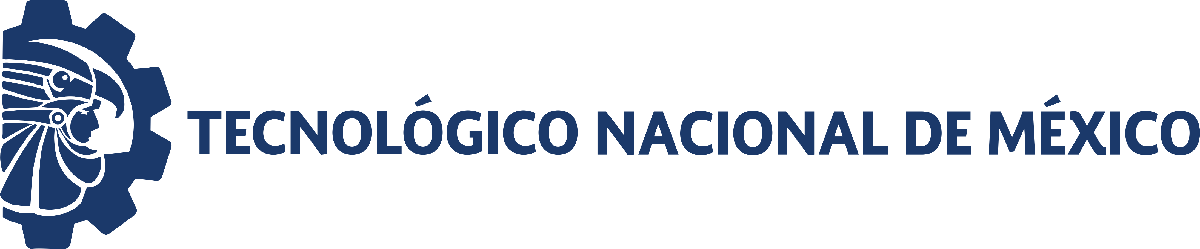                                 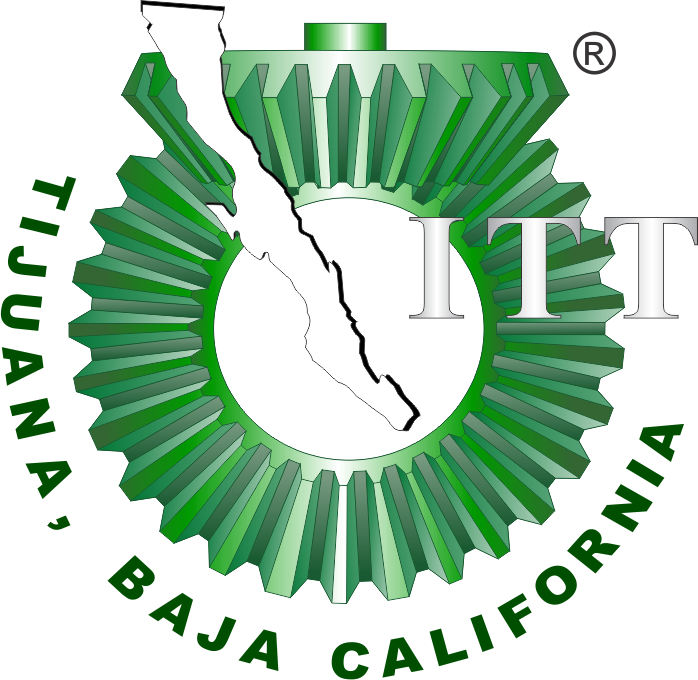

# Práctica 2: Sistema Respiratorio 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general                                                                                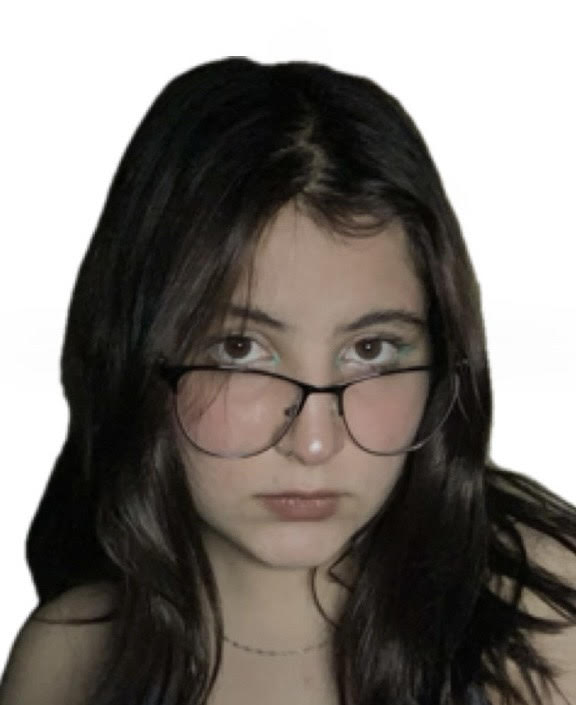

Nombre del alumno: Kenia Celeste Acosta Berrelleza 

Número de control: 22210407

Correo institucional:l22210407@tectijuana.edu.mxAsignatura:                                                                     

 **Modelado de Sistemas Fisiológicos                                                                                                              **

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '30';
file = 'Respiratorio';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';


## Rendimiento del controlador

kP=

kl=

kD=

Settling time=

Overshoot=

Peak=

## Respiracion normal

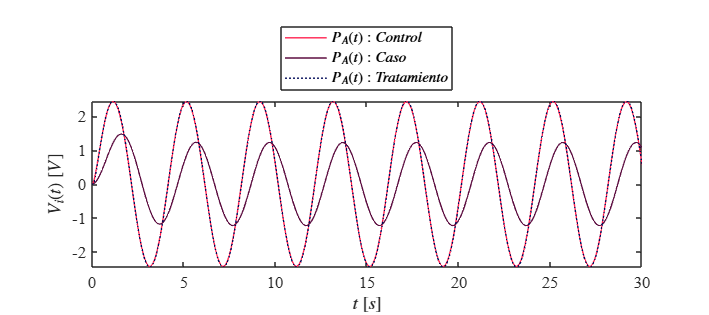

set_param('Respiratorio/Pao(t)','sw','1');
set_param('Respiratorio/PID Controller','P','16.8319465963119');
set_param('Respiratorio/PID Controller','I','330.170634097693');
set_param('Respiratorio/PID Controller','D','-0.0537842799460082');
Signal = 'Respiracion normal';
N = sim(file,parameters);
plotsignal(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Respiracion anormal

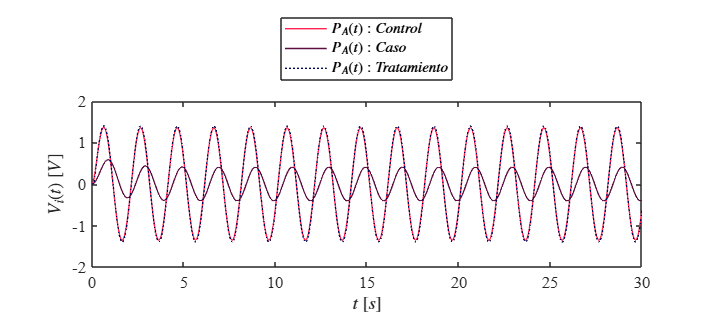

set_param('Respiratorio/Pao(t)','sw','0');
set_param('Respiratorio/PID Controller','P','16.8319465963119');
set_param('Respiratorio/PID Controller','I','330.170634097693');
set_param('Respiratorio/PID Controller','D','-0.0537842799460082');
Signal = 'Respiracion anormal';
N = sim(file,parameters);
plotsignal(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Funcion:Respuesta a las señales

function plotsignal(t, PAx, PAy, PAz, Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(12, 'points')
   rosa = [255/255, 32/255, 78/255];
   blue = [0/255,9/255,87/255];
   morado = [93/255, 14/255, 65/255];

    hold on; grid off; box on

    t = t(:);

    % Convertir objetos timeseries a arreglos numéricos
    if isa(PAx, 'timeseries'), PAx = PAx.Data(:); end
    if isa(PAy, 'timeseries'), PAy = PAy.Data(:); end
    if isa(PAz, 'timeseries'), PAz = PAz.Data(:); end


    plot(t, PAx, 'LineWidth', 1,'Color',rosa)
    plot(t, PAy, 'LineWidth', 1,'Color', morado)
    plot(t, PAz,':', 'LineWidth', 1,'Color', blue)

    xlabel('$t$ $[s]$',  'Interpreter','Latex')
    ylabel('$V_i (t)$ $[V]$',  'Interpreter','Latex')

   L = legend('$P_A(t): Control$', '$P_A(t): Caso$', '$P_A(t): Tratamiento$');
    set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')

    if Signal == "Respiración normal"
        xlim([0, 30]); xticks(0:1:30)
        ylim([-3, 3]); yticks(-3:0.5:3)

    elseif Signal == "Respiración Anormal"
        xlim([0, 30]); xticks(0:1:30)
        ylim([-3, 3]); yticks(-3:0.5:3)

    end

end
